# SC42025 Filtering & Identification

## MATLAB EXERCISE HW2

#### Instructions: Fill in the live script with your code and answers. Then export the live script as a pdf (in the 'Live Editor tab', click on the arrow under 'Save' and then 'Export to pdf').

We want to localize a vehicle with GPS data. However the data is noisy and we cannot accurately estimate the state of the vehicle relying merely on the GPS signal. In order to improve the estimate, we wish to combine the data with vehicle acceleration measurements from an accelerometer mounted on the vehicle.


$$\mathit{\mathbf{x}}={\left\lbrack \begin{array}{cc}
{\mathit{\mathbf{p}}}^{\mathrm{T}}  & {\mathit{\mathbf{v}}}^{\mathrm{T}} 
\end{array}\right\rbrack }^{\mathrm{T}}$$


Where $\mathit{\mathbf{p}}={\left\lbrack \begin{array}{cc}
p_x  & p_y 
\end{array}\right\rbrack }^{\mathrm{T}}$ and $\mathit{\mathbf{v}}={\left\lbrack \begin{array}{cc}
v_x  & v_y 
\end{array}\right\rbrack }^{\mathrm{T}}$ are the vector position and velocity in the ground plane respectively. The equations of motion are


$${\mathit{\mathbf{p}}}_k ={\mathit{\mathbf{p}}}_{k-1} +{\mathit{\mathbf{v}}}_{k-1} \Delta t+\frac{1}{2}{\mathit{\mathbf{a}}}_{k-1} \Delta t^2$$



$${\mathit{\mathbf{v}}}_k ={\mathit{\mathbf{v}}}_{k-1} +{\mathit{\mathbf{a}}}_{k-1} \Delta t$$


Where ${\mathit{\mathbf{a}}}_k$ is the acceleration vector at time step k. It is determined using the measured acceleration $\tilde{\mathit{\mathbf{a}}}$ from the accelerometer as


$$\mathbf{\textit{a}}_k = \mathbf{\tilde{\textit{a}}}_k + \epsilon_k \qquad \epsilon_k \sim \mathcal{N}(0, \sigma_e^2I_{2\times2})$$


The accelerometer compensates for the acceleration due to gravity, and therefore only the vehicle accelerations are recorded.

At each time step we also have available measured GPS state information as


$$\mathbf{\textit{z}}_k =\left[\matrix{ \mathbf{\textit{p}}_k  \cr \mathbf{\textit{v}}_k  } \right] + \eta_k \qquad \eta_k \sim \mathcal{N}(0, R)$$


It is given that $\sigma_e =0\ldotp 3\;{\textrm{ms}}^{-2}$ and $R=\textrm{diag}\left(3^2 ,3^2 ,0\ldotp {03}^2 ,0\ldotp {03}^2 \right)$. The timestep $\Delta t=0\ldotp 1\mathrm{s}$, and the total time-period of the trial is 10s. The vehicle is at the origin with zero velocity at the beginning of the trial. Also important to note here is that all the measurements are already in the global coordinate system, so no coordinate transformations are required.

Using the given equations, model a state space equation of the form


$$      \mathbf{\textit{x}}_{k+1} = A\mathbf{\textit{x}}_{k} + B\tilde{\mathbf{\textit{a}}}_k + w_k  \qquad w_k \sim \mathcal{N}(0,Q)\\
       \mathbf{\textit{z}}_k = C\mathbf{\textit{x}}_{k} + \eta_k \qquad \eta_k \sim \mathcal{N}(0, R)$$


Note that in the above state space model, the measured accelerations are used as an input to the system, while the GPS measurements are considered as the outputs. 

What are the matrices $A,B,C\;\textrm{and}\;Q$ ?

YOUR ANSWER HERE

$A=\left\lbrack \begin{array}{cccc}
1 & 0 & 0\ldotp 1 & 0\\
0 & 1 & 0 & 0\ldotp 1\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$ , $B=\left\lbrack \begin{array}{cc}
0\ldotp 005 & 0\\
0 & 0\ldotp 005\\
0\ldotp 1 & 0\\
0 & 0\ldotp 1
\end{array}\right\rbrack$, $C=\left\lbrack \begin{array}{cccc}
1 & 0 & 0 & 0\\
0 & 1 & 0 & 0\\
0 & 0 & 1 & 0\\
0 & 0 & 0 & 1
\end{array}\right\rbrack$, $Q=\left\lbrack \begin{array}{cccc}
0\ldotp 005\sigma_e^2  & 0 & \sqrt{0\ldotp 0005}\sigma_e^2 \approx 0\ldotp 0223 & 0\\
0 & 0\ldotp 005\sigma_e^2  & 0 & \sqrt{0\ldotp 0005}\sigma_e^2 \approx 0\ldotp 0223\\
\sqrt{0\ldotp 0005}\sigma_e^2 \approx 0\ldotp 0223 & 0 & 0\ldotp 1\sigma_e^2  & 0\\
0 & \sqrt{0\ldotp 0005}\sigma_e^2 \approx 0\ldotp 0223 & 0 & 0\ldotp 1\sigma_e^2 
\end{array}\right\rbrack$

Import the data from the file *data_hw2.mat* file. It contains the noisy accelerometer readings (${\tilde{\mathit{\mathbf{a}}} }_k$), and the GPS state measurements(${\mathit{\mathbf{z}}}_k$). Using the acceleration measurements simulate the state space model. 

clear; clc; close all;

data = load("data_hw2.mat")

data = struct with fields:
    a_meas: [2×101 double]
    z_meas: [101×4 double]



A_mod = [1 0 0.1 0;
    0 1 0 0.1;
    0 0 1 0;
    0 0 0 1];
B_mod = [0.005 0;
    0 0.005;
    0.1 0;
    0 0.1];
C_mod = eye(4);
D_mod = zeros(4, 2);

A1 = [0 0 1 0;
    0 0 0 1;
    0 0 0 0;
    0 0 0 0];
B1 = [0 0;
    0 0;
    1 0;
    0 1;];

sys = ss(A_mod, B_mod, C_mod, D_mod, Ts=0.1);
t = 0:0.1:10;
u = (data.a_meas).';
y = ones(4, 100);
x = [0;0;0;0]

x =      0
     0
     0
     0


for i = 1:100
    x = x + 0.1*A1*x + 0.1*B1*u(i, :).';
    y(:, i) = C_mod*x;
end
x_traj_sim = lsim(sys, u, t)

x_traj_sim =          0         0         0         0
    0.0053   -0.0022    0.1069   -0.0442
    0.0193   -0.0061    0.1723   -0.0329
    0.0439   -0.0069    0.3197    0.0162
    0.0842   -0.0043    0.4857    0.0357
    0.1409   -0.0000    0.6482    0.0500
    0.2139    0.0084    0.8122    0.1175
    0.3013    0.0263    0.9363    0.2414
    0.4033    0.0531    1.1043    0.2940
    0.5240    0.0853    1.3097    0.3513


*Hint: You can use the function lsim() for simulating the state space model*.

From the GPS data, plot the measured position (in the 2D plane) and the vehicle speed.

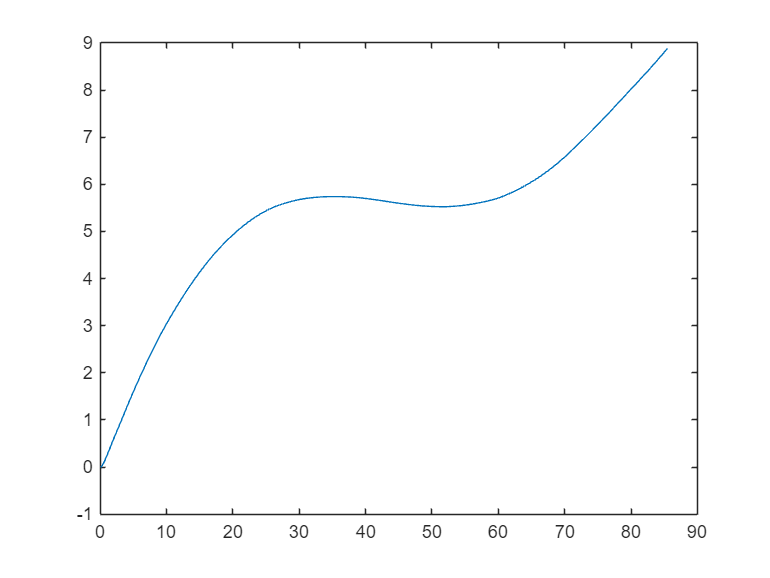

plot(x_traj_sim(:, 1), x_traj_sim(:, 2))

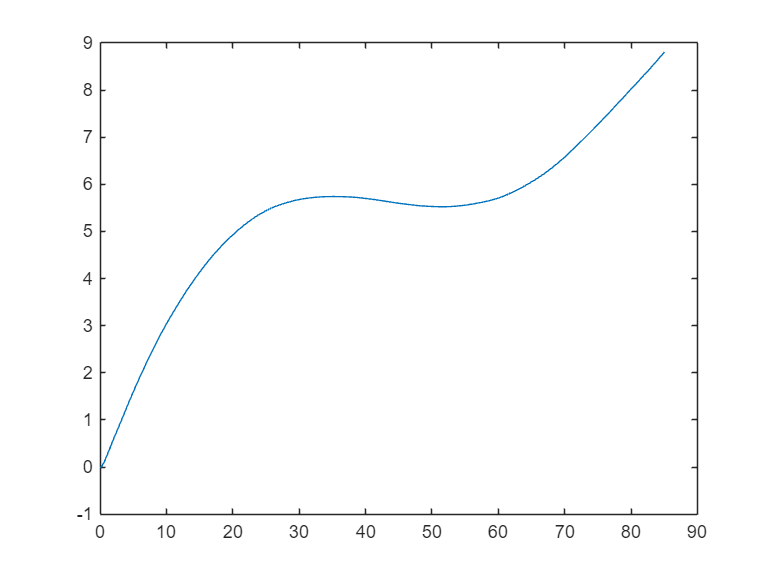

plot(y(1, :), y(2, :))

Construct an asymptotic Luenberger observer such that the poles of the observer model are placed at *diag(0.95, 0.95, 0.9, 0.9) *i.e. construct a system of the form


$${\hat{\mathit{\mathbf{x}}} }_{k+1} =\left(A-KC\right){\hat{\mathit{\mathbf{x}}} }_k +B{\tilde{\mathit{\mathbf{a}}} }_k +K{\mathit{\mathbf{z}}}_{\mathrm{meas},\;k}$$



$${\hat{\mathit{\mathbf{z}}} }_k =C{\hat{\mathit{\mathbf{x}}} }_k$$


Simulate the system using the acceleration measurements(${\tilde{\mathit{\mathbf{a}}} }_k$) and the GPS readings (${\mathit{\mathbf{z}}}_{\textrm{meas}}$). 

p = [0.95, 0.95, 0.9, 0.9];

C_obs = eye(4);
D_obs = zeros(4, 6);
K = place(A_mod', C_obs, p')';
B_obs = [B_mod K]

B_obs =     0.0050         0    0.0500         0    0.1000         0
         0    0.0050         0    0.0500         0    0.1000
    0.1000         0         0         0    0.1000         0
         0    0.1000         0         0         0    0.1000


A_obs = A_mod-K*C_obs

A_obs =     0.9500         0         0         0
         0    0.9500         0         0
         0         0    0.9000         0
         0         0         0    0.9000



u_observer = [u data.z_meas];

observer = ss(A_obs, B_obs, C_obs, D_obs, Ts=0.1);
x_obs = lsim(observer, u_observer, t)

x_obs =          0         0         0         0
   -0.0286   -0.1174    0.1062   -0.0450
    0.0558   -0.1923    0.1736   -0.0336
   -0.0383   -0.2497    0.3268    0.0168
    0.1775   -0.3672    0.4891    0.0382
    0.4356   -0.3379    0.6478    0.0568
    0.4328   -0.2732    0.8069    0.1252
    0.7624   -0.3132    0.9213    0.2480
    0.7072   -0.2976    1.0906    0.3013
    0.8431   -0.1484    1.2989    0.3562


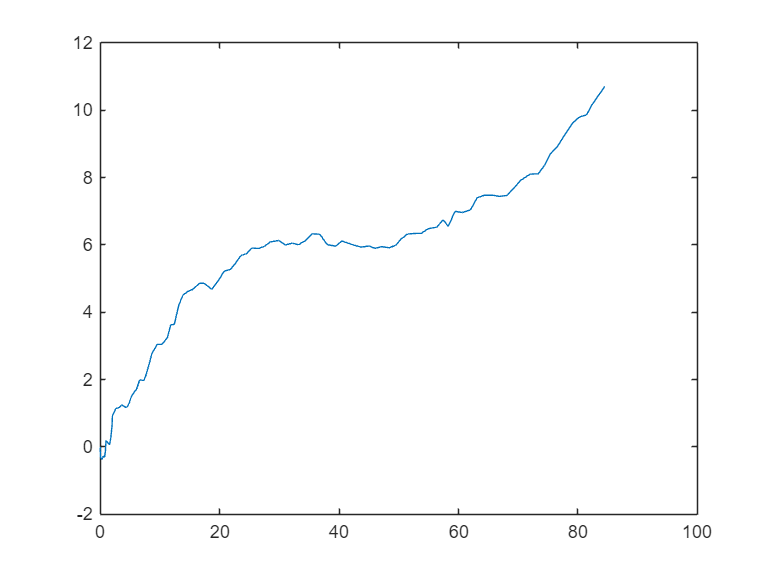

plot(x_obs(:, 1), x_obs(:, 2))

*Hint: You can use the command K = place(A',C',p)' to find K for the given poles.*

Construct a Kalman Filter to estimate the state of the given state space model, using the same data as done in the previous section. No use of MATLAB toolboxes is allowed, you need to implement the Kalman Filter by yourself. Use the matrix $Q$ you found in the  first question, and the matrix $R$ as given.

sigma_e = 0.3;
Q_0 = [0.005*sigma_e^2 0 sqrt(0.0005)*sigma_e^2 0;
    0 0.005*sigma_e^2 0 sqrt(0.0005)*sigma_e^2;
    sqrt(0.0005)*sigma_e^2 0 0.1*sigma_e^2 0;
    0 sqrt(0.0005)*sigma_e^2 0 0.1*sigma_e^2];
Q = Q_0;

R_0 = diag([9, 9, 0.03*0.03 0.03*0.03]);
R = R_0;

P = [0 0 0 0;
    0 0 0 0;
    0 0 0 0;
    0 0 0 0];

x_hat = [0; 0; 0; 0];
x_filt = zeros(101, 4);
x_filt(1, :) = x_hat;
for i = 1:101
    % prediction step
    x_hat = A_mod*x_hat + B_mod * u(i, :).';
    P = A_mod * P * A_mod' + Q;
    
    % correction step
    K = P*C_mod'/(C_mod*P*C_mod'+R);
    x_hat = x_hat + K*(u_observer(i, 3:6)' - C_mod'*x_hat);
    P = (eye(4) - K*C_mod)*P;
    x_filt(i, :) = x_hat;
end

Load the file *ground_truth_hw2.mat. *This file contains the actual states of the vehicle. Plot the true position in the 2D plane, along with the simulated, Luenberger observer estimate, and Kalman Filter estimate in a graph. In another figure, plot the magnitude of the true vehicle velocity, with the simulated, Luenberger observer estimate, and Kalman Filter estimate

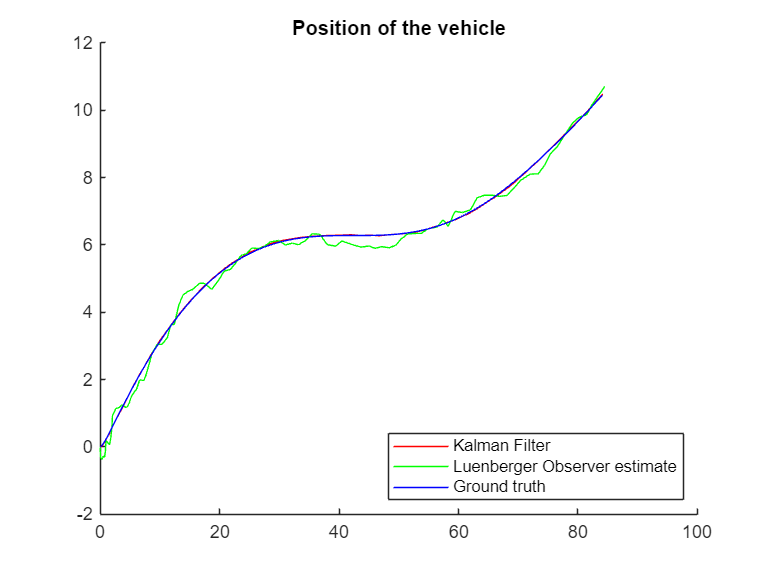

ground_truth = load("ground_truth_hw2.mat").z_true;
figure;
hold on
p1 = plot(x_filt(:, 1), x_filt(:, 2), 'r', DisplayName='Kalman Filter');
p2 = plot(x_obs(:, 1), x_obs(:, 2), 'g', DisplayName='Luenberger Observer estimate');
p3 = plot(ground_truth(:, 1), ground_truth(:, 2), 'b', DisplayName='Ground truth');
legend([], Location='southeast', AutoUpdate='off');

title("Position of the vehicle");
hold off

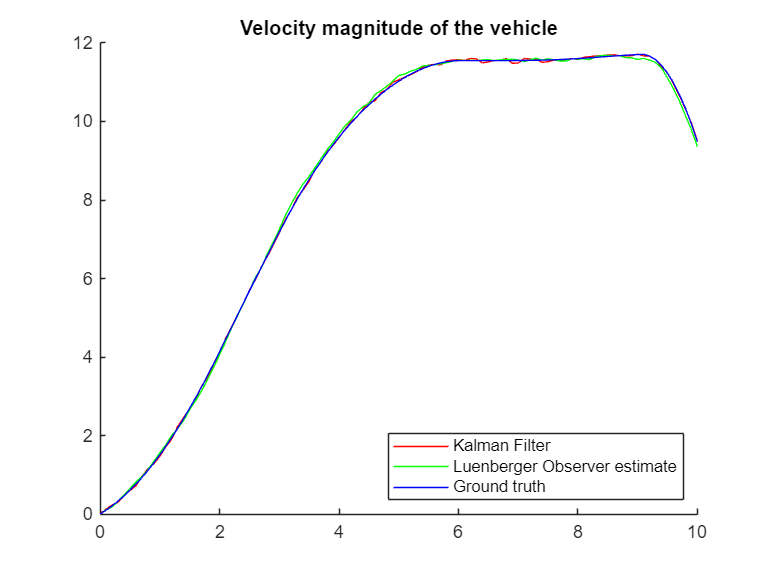

% hold on
% p1 = plot(x_filt(:, 3), x_filt(:, 4), 'r');
% p2 = plot(x_obs(:, 3), x_obs(:, 4), 'g');
% p3 = plot(ground_truth(:, 1), ground_truth(:, 2), 'b');
% legend([p1, p2, p3], 'Kalman Filter estimate', 'Luenberger Observer estimate', 'Ground truth', Location='southeast', AutoUpdate='off');
% 
% title("Position of the vehicle");
% hold off
figure;
hold on
p1 = plot(t, vecnorm([x_filt(:, 3) x_filt(:, 4)].'), 'r', DisplayName='Kalman Filter');
p2 = plot(t, vecnorm([x_obs(:, 3), x_obs(:, 4)].'), 'g', DisplayName='Luenberger Observer estimate');
p3 = plot(t, vecnorm([ground_truth(:, 3), ground_truth(:, 4)].'), 'b', DisplayName='Ground truth');
legend([], Location='southeast', AutoUpdate='off');
% plot(u_observer(:, 5), u_observer(:, 6))
title("Velocity magnitude of the vehicle");
hold off